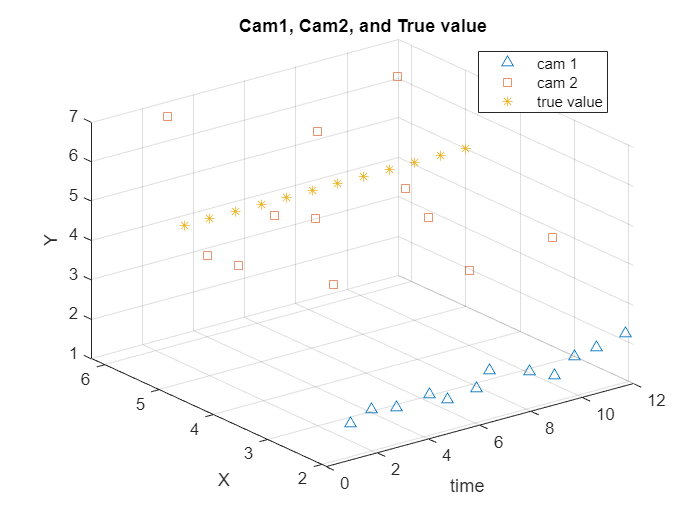

X_true_value = ones(1, 12) * 5;
Y_true_value = ones(1, 12) * 5;

time = 1:12;

X1 = cam1(:, 1);
Y1 = cam1(:, 2);

X2 = cam2(:, 1);
Y2 = cam2(:, 2);

figure;

% Cam1 Plot
plot3(time,X1, Y1, '^', 'DisplayName', 'cam 1');
hold on;

% Cam2 Plot
plot3(time,X2, Y2, 's', 'DisplayName', 'cam 2');

% Plot true values
plot3(time,X_true_value, Y_true_value, '*', 'DisplayName', 'true value');

xlabel('time');
ylabel('X');
zlabel('Y')
title('Cam1, Cam2, and True value');
legend('Location', 'best')
grid on; 

%Full scale Accuracy
Accuracy1 = sum(sqrt((X1-transpose(X_true_value)).^2+(Y1-transpose(Y_true_value)).^2))/(12*5)*100

Accuracy1 = 85.2042

Accuracy2 = sum(sqrt((X2-transpose(X_true_value)).^2+(Y2-transpose(Y_true_value)).^2))/(12*5)*100

Accuracy2 = 26.0225


precision1 = std(X1,Y1)

precision1 = 0.0843

precision2 = std(X2,Y2)

precision2 = 0.9202